%~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% Satellite Tracker Setup Code
%~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% This code uses TLE files from NORAD for active satellites,
% extracts satellite data from TLE, and propagates the orbit
% using the orbit.m function and RK4 numerical propagator.
% The propagated data is further converted into range, azimuth, and
% elevation with respect to a specific ground station. When 
% the satellite passes over the ground station, it gets tracked in.
% The code provides visibility opportunities of the satellite at 
% the ground station, offers a skyplot of every satellite passing
% over, and further provides a 2D plot of propagated orbits. 
%~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% Input: NORAD TLE of satellites and latitude, longitude of the Ground 
%        station.
% Output: Visibility of satellites & their skyplot over the ground 
%         station. Additionally, a 2D plot of propagated orbits. 
%~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

clc
clear all
format long g

% Constants
ge = 398600.8; % Earth gravitational constant [km3/s2]
TWOPI = 2*pi;
MINUTES_PER_DAY = 1440;
MINUTES_PER_DAY_SQUARED = (MINUTES_PER_DAY * MINUTES_PER_DAY);
MINUTES_PER_DAY_CUBED = (MINUTES_PER_DAY * MINUTES_PER_DAY_SQUARED);

% TLE file name
fname = 'NORAD_180124.txt';

% Open the TLE file
fid = fopen(fname, 'r');

% Store TLE data for each satellite in a cell array
satData = {};

% Process each satellite's TLE entry
while ~feof(fid)
    % Read satellite name
    satName = fgetl(fid);

    % Read TLE line 1
    tline1 = fgetl(fid);
    Cnum = tline1(3:7);
    SC = tline1(8);
    ID = tline1(10:17);
    year = str2num(tline1(19:20));
    doy = str2num(tline1(21:32));
    epoch = str2num(tline1(19:32));
    TD1 = str2num(tline1(34:43));
    TD2 = str2num(tline1(45:50));
    ExTD2 = str2num(tline1(51:52));
    BStar = str2num(tline1(54:59));
    ExBStar = str2num(tline1(60:61));
    BStar = BStar * 1e-5 * 10^ExBStar;
    Etype = tline1(63);
    Enum = str2num(tline1(65:end));

    % Read TLE line 2
    tline2 = fgetl(fid);
    i = str2num(tline2(9:16));
    raan = str2num(tline2(18:25));
    e = str2num(strcat('0.', tline2(27:33)));
    omega = str2num(tline2(35:42));
    M = str2num(tline2(44:51));
    no = str2num(tline2(53:63));
    a = (ge / (no * 2 * pi / 86400)^2)^(1/3);
    rNo = str2num(tline2(65:end));

    % Create a structure for this satellite's data
    satellitedata = struct( ...
        'epoch', epoch, ...
        'SatName', satName,...
        'norad_number', Cnum, ...
        'bulletin_number', ID, ...
        'classification', SC, ...
        'revolution_number', rNo, ...
        'ephemeris_type', Etype, ...
        'meanAno', M * (pi/180), ...
        'RAAN', raan * (pi/180), ...
        'ArgP', omega * (pi/180), ...
        'Incl', i * (pi/180), ...
        'Eccn', e, ...
        'SemiMAx', a,...
        'xno', no * TWOPI / MINUTES_PER_DAY, ...
        'xndt2o', TD1 * TWOPI / MINUTES_PER_DAY_SQUARED, ...
        'xndd6o', TD2 * 10^ExTD2 * TWOPI / MINUTES_PER_DAY_CUBED, ...
        'bstar', BStar ...
    );

    % Add this satellite's data to the cell array
    satData{end+1} = satellitedata;
end

fclose(fid);

satProp = {};  % Pre-allocate struct array to store propagation results
numSats = size(satData, 2);  % Number of satellites

h = waitbar(0, 'Propagating Satellites...');  % Create progress bar

for i = 1:numSats
    % Extract orbital elements for the current satellite
    semiMAx = satData{1, i}.SemiMAx;
    eccn = satData{1, i}.Eccn;
    incl = satData{1, i}.Incl;
    RAAN = satData{1, i}.RAAN;
    ArgP = satData{1, i}.ArgP;
    meanAno = satData{1, i}.meanAno;

    % Convert orbital elements to states
    Satrv = Kep2States(semiMAx, eccn, incl, RAAN, ArgP, meanAno);

    % Propagate the orbit
    [Lat, Lon, Alt, XSat, YSat, ZSat, TS] = propagator(Satrv, 2024, 1, 2, 12, 24, 40, 1, 5);

    % Save results
    satProp{i} = struct('Lat', Lat, 'Lon', Lon, 'Alt', Alt, 'XSat', XSat, 'YSat', YSat, 'ZSat', ZSat, 'TS', TS);

    waitbar(i/numSats, h, sprintf('Propagating Satellite %d/%d', i, numSats));  % Update progress bar
end

close(h);

% Define ground station latitude and longitude
gsLat = 18.4848;  % ground station latitude
gsLon = 74.0109; % ground station longitude

% Minimum elevation angle for visibility (in degrees)
minElevation = 5;  

% Initialize variables to store az and el values
az_idx = [];
el_idx = [];

% Create a new figure for the skyplot
figure;

% Initialize cell arrays to store az and el values for each satellite
az_all = cell(1, numSats);
el_all = cell(1, numSats);

% Loop through each satellite
for i = 1:numSats
    satLat = satProp{i}.Lat;
    satLon = satProp{i}.Lon;
    satAlt = satProp{i}.Alt;
    satTS = satProp{i}.TS;

    wgs84 = wgs84Ellipsoid;

    % Calculate angular separation between satellite and ground station
    [az, el, r] = geodetic2aer(satLon, satLat, satAlt, gsLon, gsLat, minElevation, wgs84);

    % Find indices where elevation is above the minimum threshold
    idx = find(el > minElevation);

    if ~isempty(idx)
        % Satellite is visible at some point
        fprintf('Satellite %s is visible over the ground station.\n', satData{1, i}.SatName);

        % Find pass times
        passTimes = satProp{i}.TS(idx);
        passTime_GD = JD2UTC(passTimes);
        numpasstime = size(passTime_GD, 1);

        % Extract and print pass times
        for j = 1:numpasstime
            year = passTime_GD(j, 1);
            month = passTime_GD(j, 2);
            day = passTime_GD(j, 3);
            hour = passTime_GD(j, 4);
            minute = passTime_GD(j, 5);
            second = passTime_GD(j, 6);

            passTimeSTR = sprintf('%04d/%02d/%02d/%02d:%02d:%02d', year, month, day, hour, minute, second);

            fprintf('Pass times (UTCG): %s\n', passTimeSTR);
        end

        % Store az and el values corresponding to positive elevation indices
        az_all{1, i} = az(idx);
        el_all{1, i} = el(idx);
    end
end

Satellite OPS 8701 (DSP 10)        is visible over the ground station.


Pass times (UTCG): 2024/01/03/11:16:44
Pass times (UTCG): 2024/01/03/11:16:49
Pass times (UTCG): 2024/01/03/11:16:54
Pass times (UTCG): 2024/01/03/11:16:59
Pass times (UTCG): 2024/01/03/11:17:04
Pass times (UTCG): 2024/01/03/11:17:09
Pass times (UTCG): 2024/01/03/11:17:14
Pass times (UTCG): 2024/01/03/11:17:19
Pass times (UTCG): 2024/01/03/11:17:24
Pass times (UTCG): 2024/01/03/11:17:29
Pass times (UTCG): 2024/01/03/11:17:34
Pass times (UTCG): 2024/01/03/11:17:39
Pass times (UTCG): 2024/01/03/11:17:44
Pass times (UTCG): 2024/01/03/11:17:49
Pass times (UTCG): 2024/01/03/11:17:54
Pass times (UTCG): 2024/01/03/11:17:59
Pass times (UTCG): 2024/01/03/11:18:04
Pass times (UTCG): 2024/01/03/11:18:09
Pass times (UTCG): 2024/01/03/11:18:14
Pass times (UTCG): 2024/01/03/11:18:19
Pass times (UTCG): 2024/01/03/11:18:24
Pass times (UTCG): 2024/01/03/11:18:29
Pass times (UTCG): 2024/01/03/11:18:34
Pass times (UTCG): 2024/01/03/11:18:39
Pass times (UTCG): 2024/01/03/11:18:44
Pass times (UTCG): 2024/0

Satellite PHASE 3B (AO-10)         is visible over the ground station.


Pass times (UTCG): 2024/01/02/15:55:25
Pass times (UTCG): 2024/01/02/15:55:30
Pass times (UTCG): 2024/01/02/15:55:35
Pass times (UTCG): 2024/01/02/15:55:40
Pass times (UTCG): 2024/01/02/15:55:45
Pass times (UTCG): 2024/01/02/15:55:50
Pass times (UTCG): 2024/01/02/15:55:55
Pass times (UTCG): 2024/01/02/15:56:00
Pass times (UTCG): 2024/01/02/15:56:05
Pass times (UTCG): 2024/01/02/15:56:10
Pass times (UTCG): 2024/01/02/15:56:15
Pass times (UTCG): 2024/01/02/15:56:20
Pass times (UTCG): 2024/01/02/15:56:25
Pass times (UTCG): 2024/01/02/15:56:30
Pass times (UTCG): 2024/01/02/15:56:35
Pass times (UTCG): 2024/01/02/15:56:40
Pass times (UTCG): 2024/01/02/15:56:45
Pass times (UTCG): 2024/01/02/15:56:50
Pass times (UTCG): 2024/01/02/15:56:55
Pass times (UTCG): 2024/01/02/15:57:00
Pass times (UTCG): 2024/01/02/15:57:05
Pass times (UTCG): 2024/01/02/15:57:10
Pass times (UTCG): 2024/01/02/15:57:15
Pass times (UTCG): 2024/01/02/15:57:20
Pass times (UTCG): 2024/01/02/15:57:25
Pass times (UTCG): 2024/0

Satellite TDRS 3                   is visible over the ground station.


Pass times (UTCG): 2024/01/03/06:11:03
Pass times (UTCG): 2024/01/03/06:11:08
Pass times (UTCG): 2024/01/03/06:11:13
Pass times (UTCG): 2024/01/03/06:11:18
Pass times (UTCG): 2024/01/03/06:11:23
Pass times (UTCG): 2024/01/03/06:11:28
Pass times (UTCG): 2024/01/03/06:11:33
Pass times (UTCG): 2024/01/03/06:11:38
Pass times (UTCG): 2024/01/03/06:11:43
Pass times (UTCG): 2024/01/03/06:11:48
Pass times (UTCG): 2024/01/03/06:11:53
Pass times (UTCG): 2024/01/03/06:11:58
Pass times (UTCG): 2024/01/03/06:12:03
Pass times (UTCG): 2024/01/03/06:12:08
Pass times (UTCG): 2024/01/03/06:12:13
Pass times (UTCG): 2024/01/03/06:12:18
Pass times (UTCG): 2024/01/03/06:12:23
Pass times (UTCG): 2024/01/03/06:12:28
Pass times (UTCG): 2024/01/03/06:12:33
Pass times (UTCG): 2024/01/03/06:12:38
Pass times (UTCG): 2024/01/03/06:12:43
Pass times (UTCG): 2024/01/03/06:12:48
Pass times (UTCG): 2024/01/03/06:12:53
Pass times (UTCG): 2024/01/03/06:12:58
Pass times (UTCG): 2024/01/03/06:13:03
Pass times (UTCG): 2024/0

Satellite FLTSATCOM 8 (USA 46)     is visible over the ground station.


Pass times (UTCG): 2024/01/03/03:41:48
Pass times (UTCG): 2024/01/03/03:41:53
Pass times (UTCG): 2024/01/03/03:41:58
Pass times (UTCG): 2024/01/03/03:42:03
Pass times (UTCG): 2024/01/03/03:42:08
Pass times (UTCG): 2024/01/03/03:42:13
Pass times (UTCG): 2024/01/03/03:42:18
Pass times (UTCG): 2024/01/03/03:42:23
Pass times (UTCG): 2024/01/03/03:42:28
Pass times (UTCG): 2024/01/03/03:42:33
Pass times (UTCG): 2024/01/03/03:42:38
Pass times (UTCG): 2024/01/03/03:42:43
Pass times (UTCG): 2024/01/03/03:42:48
Pass times (UTCG): 2024/01/03/03:42:53
Pass times (UTCG): 2024/01/03/03:42:58
Pass times (UTCG): 2024/01/03/03:43:03
Pass times (UTCG): 2024/01/03/03:43:08
Pass times (UTCG): 2024/01/03/03:43:13
Pass times (UTCG): 2024/01/03/03:43:18
Pass times (UTCG): 2024/01/03/03:43:23
Pass times (UTCG): 2024/01/03/03:43:28
Pass times (UTCG): 2024/01/03/03:43:33
Pass times (UTCG): 2024/01/03/03:43:38
Pass times (UTCG): 2024/01/03/03:43:43
Pass times (UTCG): 2024/01/03/03:43:48
Pass times (UTCG): 2024/0

Satellite SKYNET 4C                is visible over the ground station.


Pass times (UTCG): 2024/01/03/02:58:43
Pass times (UTCG): 2024/01/03/02:58:48
Pass times (UTCG): 2024/01/03/02:58:53
Pass times (UTCG): 2024/01/03/02:58:58
Pass times (UTCG): 2024/01/03/02:59:03
Pass times (UTCG): 2024/01/03/02:59:08
Pass times (UTCG): 2024/01/03/02:59:13
Pass times (UTCG): 2024/01/03/02:59:18
Pass times (UTCG): 2024/01/03/02:59:23
Pass times (UTCG): 2024/01/03/02:59:28
Pass times (UTCG): 2024/01/03/02:59:33
Pass times (UTCG): 2024/01/03/02:59:38
Pass times (UTCG): 2024/01/03/02:59:43
Pass times (UTCG): 2024/01/03/02:59:48
Pass times (UTCG): 2024/01/03/02:59:53
Pass times (UTCG): 2024/01/03/02:59:58
Pass times (UTCG): 2024/01/03/03:00:03
Pass times (UTCG): 2024/01/03/03:00:08
Pass times (UTCG): 2024/01/03/03:00:13
Pass times (UTCG): 2024/01/03/03:00:18
Pass times (UTCG): 2024/01/03/03:00:23
Pass times (UTCG): 2024/01/03/03:00:28
Pass times (UTCG): 2024/01/03/03:00:33
Pass times (UTCG): 2024/01/03/03:00:38
Pass times (UTCG): 2024/01/03/03:00:43
Pass times (UTCG): 2024/0

Satellite USA 65 (DSP 15)          is visible over the ground station.


Pass times (UTCG): 2024/01/03/09:12:44
Pass times (UTCG): 2024/01/03/09:12:49
Pass times (UTCG): 2024/01/03/09:12:54
Pass times (UTCG): 2024/01/03/09:12:59
Pass times (UTCG): 2024/01/03/09:13:04
Pass times (UTCG): 2024/01/03/09:13:09
Pass times (UTCG): 2024/01/03/09:13:14
Pass times (UTCG): 2024/01/03/09:13:19
Pass times (UTCG): 2024/01/03/09:13:24
Pass times (UTCG): 2024/01/03/09:13:29
Pass times (UTCG): 2024/01/03/09:13:34
Pass times (UTCG): 2024/01/03/09:13:39
Pass times (UTCG): 2024/01/03/09:13:44
Pass times (UTCG): 2024/01/03/09:13:49
Pass times (UTCG): 2024/01/03/09:13:54
Pass times (UTCG): 2024/01/03/09:13:59
Pass times (UTCG): 2024/01/03/09:14:04
Pass times (UTCG): 2024/01/03/09:14:09
Pass times (UTCG): 2024/01/03/09:14:14
Pass times (UTCG): 2024/01/03/09:14:19
Pass times (UTCG): 2024/01/03/09:14:24
Pass times (UTCG): 2024/01/03/09:14:29
Pass times (UTCG): 2024/01/03/09:14:34
Pass times (UTCG): 2024/01/03/09:14:39
Pass times (UTCG): 2024/01/03/09:14:44
Pass times (UTCG): 2024/0

Satellite TDRS 5                   is visible over the ground station.


Pass times (UTCG): 2024/01/02/21:24:06
Pass times (UTCG): 2024/01/02/21:24:11
Pass times (UTCG): 2024/01/02/21:24:16
Pass times (UTCG): 2024/01/02/21:24:21
Pass times (UTCG): 2024/01/02/21:24:26
Pass times (UTCG): 2024/01/02/21:24:31
Pass times (UTCG): 2024/01/02/21:24:36
Pass times (UTCG): 2024/01/02/21:24:41
Pass times (UTCG): 2024/01/02/21:24:46
Pass times (UTCG): 2024/01/02/21:24:51
Pass times (UTCG): 2024/01/02/21:24:56
Pass times (UTCG): 2024/01/02/21:25:01
Pass times (UTCG): 2024/01/02/21:25:06
Pass times (UTCG): 2024/01/02/21:25:11
Pass times (UTCG): 2024/01/02/21:25:16
Pass times (UTCG): 2024/01/02/21:25:21
Pass times (UTCG): 2024/01/02/21:25:26
Pass times (UTCG): 2024/01/02/21:25:31
Pass times (UTCG): 2024/01/02/21:25:36
Pass times (UTCG): 2024/01/02/21:25:41
Pass times (UTCG): 2024/01/02/21:25:46
Pass times (UTCG): 2024/01/02/21:25:51
Pass times (UTCG): 2024/01/02/21:25:56
Pass times (UTCG): 2024/01/02/21:26:01
Pass times (UTCG): 2024/01/02/21:26:06
Pass times (UTCG): 2024/0

Satellite USA 75 (DSP 16)          is visible over the ground station.


Pass times (UTCG): 2024/01/03/01:42:17
Pass times (UTCG): 2024/01/03/01:42:22
Pass times (UTCG): 2024/01/03/01:42:27
Pass times (UTCG): 2024/01/03/01:42:32
Pass times (UTCG): 2024/01/03/01:42:37
Pass times (UTCG): 2024/01/03/01:42:42
Pass times (UTCG): 2024/01/03/01:42:47
Pass times (UTCG): 2024/01/03/01:42:52
Pass times (UTCG): 2024/01/03/01:42:57
Pass times (UTCG): 2024/01/03/01:43:02
Pass times (UTCG): 2024/01/03/01:43:07
Pass times (UTCG): 2024/01/03/01:43:12
Pass times (UTCG): 2024/01/03/01:43:17
Pass times (UTCG): 2024/01/03/01:43:22
Pass times (UTCG): 2024/01/03/01:43:27
Pass times (UTCG): 2024/01/03/01:43:32
Pass times (UTCG): 2024/01/03/01:43:37
Pass times (UTCG): 2024/01/03/01:43:42
Pass times (UTCG): 2024/01/03/01:43:47
Pass times (UTCG): 2024/01/03/01:43:52
Pass times (UTCG): 2024/01/03/01:43:57
Pass times (UTCG): 2024/01/03/01:44:02
Pass times (UTCG): 2024/01/03/01:44:07
Pass times (UTCG): 2024/01/03/01:44:12
Pass times (UTCG): 2024/01/03/01:44:17
Pass times (UTCG): 2024/0

Satellite TDRS 6                   is visible over the ground station.


Pass times (UTCG): 2024/01/03/09:51:19
Pass times (UTCG): 2024/01/03/09:51:24
Pass times (UTCG): 2024/01/03/09:51:29
Pass times (UTCG): 2024/01/03/09:51:34
Pass times (UTCG): 2024/01/03/09:51:39
Pass times (UTCG): 2024/01/03/09:51:44
Pass times (UTCG): 2024/01/03/09:51:49
Pass times (UTCG): 2024/01/03/09:51:54
Pass times (UTCG): 2024/01/03/09:51:59
Pass times (UTCG): 2024/01/03/09:52:04
Pass times (UTCG): 2024/01/03/09:52:09
Pass times (UTCG): 2024/01/03/09:52:14
Pass times (UTCG): 2024/01/03/09:52:19
Pass times (UTCG): 2024/01/03/09:52:24
Pass times (UTCG): 2024/01/03/09:52:29
Pass times (UTCG): 2024/01/03/09:52:34
Pass times (UTCG): 2024/01/03/09:52:39
Pass times (UTCG): 2024/01/03/09:52:44
Pass times (UTCG): 2024/01/03/09:52:49
Pass times (UTCG): 2024/01/03/09:52:54
Pass times (UTCG): 2024/01/03/09:52:59
Pass times (UTCG): 2024/01/03/09:53:04
Pass times (UTCG): 2024/01/03/09:53:09
Pass times (UTCG): 2024/01/03/09:53:14
Pass times (UTCG): 2024/01/03/09:53:19
Pass times (UTCG): 2024/0

Satellite UFO 2 (USA 95)           is visible over the ground station.


Pass times (UTCG): 2024/01/02/19:18:51
Pass times (UTCG): 2024/01/02/19:18:56
Pass times (UTCG): 2024/01/02/19:19:01
Pass times (UTCG): 2024/01/02/19:19:06
Pass times (UTCG): 2024/01/02/19:19:11
Pass times (UTCG): 2024/01/02/19:19:16
Pass times (UTCG): 2024/01/02/19:19:21
Pass times (UTCG): 2024/01/02/19:19:26
Pass times (UTCG): 2024/01/02/19:19:31
Pass times (UTCG): 2024/01/02/19:19:36
Pass times (UTCG): 2024/01/02/19:19:41
Pass times (UTCG): 2024/01/02/19:19:46
Pass times (UTCG): 2024/01/02/19:19:51
Pass times (UTCG): 2024/01/02/19:19:56
Pass times (UTCG): 2024/01/02/19:20:01
Pass times (UTCG): 2024/01/02/19:20:06
Pass times (UTCG): 2024/01/02/19:20:11
Pass times (UTCG): 2024/01/02/19:20:16
Pass times (UTCG): 2024/01/02/19:20:21
Pass times (UTCG): 2024/01/02/19:20:26
Pass times (UTCG): 2024/01/02/19:20:31
Pass times (UTCG): 2024/01/02/19:20:36
Pass times (UTCG): 2024/01/02/19:20:41
Pass times (UTCG): 2024/01/02/19:20:46
Pass times (UTCG): 2024/01/02/19:20:51
Pass times (UTCG): 2024/0

Satellite USA 99 (MILSTAR-1 1)     is visible over the ground station.


Pass times (UTCG): 2024/01/02/23:30:17
Pass times (UTCG): 2024/01/02/23:30:22
Pass times (UTCG): 2024/01/02/23:30:27
Pass times (UTCG): 2024/01/02/23:30:32
Pass times (UTCG): 2024/01/02/23:30:37
Pass times (UTCG): 2024/01/02/23:30:42
Pass times (UTCG): 2024/01/02/23:30:47
Pass times (UTCG): 2024/01/02/23:30:52
Pass times (UTCG): 2024/01/02/23:30:57
Pass times (UTCG): 2024/01/02/23:31:02
Pass times (UTCG): 2024/01/02/23:31:07
Pass times (UTCG): 2024/01/02/23:31:12
Pass times (UTCG): 2024/01/02/23:31:17
Pass times (UTCG): 2024/01/02/23:31:22
Pass times (UTCG): 2024/01/02/23:31:27
Pass times (UTCG): 2024/01/02/23:31:32
Pass times (UTCG): 2024/01/02/23:31:37
Pass times (UTCG): 2024/01/02/23:31:42
Pass times (UTCG): 2024/01/02/23:31:47
Pass times (UTCG): 2024/01/02/23:31:52
Pass times (UTCG): 2024/01/02/23:31:57
Pass times (UTCG): 2024/01/02/23:32:02
Pass times (UTCG): 2024/01/02/23:32:07
Pass times (UTCG): 2024/01/02/23:32:12
Pass times (UTCG): 2024/01/02/23:32:17
Pass times (UTCG): 2024/0

Satellite UFO 4 (USA 108)          is visible over the ground station.


Pass times (UTCG): 2024/01/02/13:41:50
Pass times (UTCG): 2024/01/02/13:41:55
Pass times (UTCG): 2024/01/02/13:42:00
Pass times (UTCG): 2024/01/02/13:42:05
Pass times (UTCG): 2024/01/02/13:42:10
Pass times (UTCG): 2024/01/02/13:42:15
Pass times (UTCG): 2024/01/02/13:42:20
Pass times (UTCG): 2024/01/02/13:42:25
Pass times (UTCG): 2024/01/02/13:42:30
Pass times (UTCG): 2024/01/02/13:42:35
Pass times (UTCG): 2024/01/02/13:42:40
Pass times (UTCG): 2024/01/02/13:42:45
Pass times (UTCG): 2024/01/02/13:42:50
Pass times (UTCG): 2024/01/02/13:42:55
Pass times (UTCG): 2024/01/02/13:43:00
Pass times (UTCG): 2024/01/02/13:43:05
Pass times (UTCG): 2024/01/02/13:43:10
Pass times (UTCG): 2024/01/02/13:43:15
Pass times (UTCG): 2024/01/02/13:43:20
Pass times (UTCG): 2024/01/02/13:43:25
Pass times (UTCG): 2024/01/02/13:43:30
Pass times (UTCG): 2024/01/02/13:43:35
Pass times (UTCG): 2024/01/02/13:43:40
Pass times (UTCG): 2024/01/02/13:43:45
Pass times (UTCG): 2024/01/02/13:43:50
Pass times (UTCG): 2024/0

Satellite AMSC 1                   is visible over the ground station.


Pass times (UTCG): 2024/01/02/12:48:50
Pass times (UTCG): 2024/01/02/12:48:55
Pass times (UTCG): 2024/01/02/12:49:00
Pass times (UTCG): 2024/01/02/12:49:05
Pass times (UTCG): 2024/01/02/12:49:10
Pass times (UTCG): 2024/01/02/12:49:15
Pass times (UTCG): 2024/01/02/12:49:20
Pass times (UTCG): 2024/01/02/12:49:25
Pass times (UTCG): 2024/01/02/12:49:30
Pass times (UTCG): 2024/01/02/12:49:35
Pass times (UTCG): 2024/01/02/12:49:40
Pass times (UTCG): 2024/01/02/12:49:45
Pass times (UTCG): 2024/01/02/12:49:50
Pass times (UTCG): 2024/01/02/12:49:55
Pass times (UTCG): 2024/01/02/12:50:00
Pass times (UTCG): 2024/01/02/12:50:05
Pass times (UTCG): 2024/01/02/12:50:10
Pass times (UTCG): 2024/01/02/12:50:15
Pass times (UTCG): 2024/01/02/12:50:20
Pass times (UTCG): 2024/01/02/12:50:25
Pass times (UTCG): 2024/01/02/12:50:30
Pass times (UTCG): 2024/01/02/12:50:35
Pass times (UTCG): 2024/01/02/12:50:40
Pass times (UTCG): 2024/01/02/12:50:45
Pass times (UTCG): 2024/01/02/12:50:50
Pass times (UTCG): 2024/0

Satellite TDRS 7                   is visible over the ground station.


Pass times (UTCG): 2024/01/02/21:58:46
Pass times (UTCG): 2024/01/02/21:58:51
Pass times (UTCG): 2024/01/02/21:58:56
Pass times (UTCG): 2024/01/02/21:59:01
Pass times (UTCG): 2024/01/02/21:59:06
Pass times (UTCG): 2024/01/02/21:59:11
Pass times (UTCG): 2024/01/02/21:59:16
Pass times (UTCG): 2024/01/02/21:59:21
Pass times (UTCG): 2024/01/02/21:59:26
Pass times (UTCG): 2024/01/02/21:59:31
Pass times (UTCG): 2024/01/02/21:59:36
Pass times (UTCG): 2024/01/02/21:59:41
Pass times (UTCG): 2024/01/02/21:59:46
Pass times (UTCG): 2024/01/02/21:59:51
Pass times (UTCG): 2024/01/02/21:59:56
Pass times (UTCG): 2024/01/02/22:00:01
Pass times (UTCG): 2024/01/02/22:00:06
Pass times (UTCG): 2024/01/02/22:00:11
Pass times (UTCG): 2024/01/02/22:00:16
Pass times (UTCG): 2024/01/02/22:00:21
Pass times (UTCG): 2024/01/02/22:00:26
Pass times (UTCG): 2024/01/02/22:00:31
Pass times (UTCG): 2024/01/02/22:00:36
Pass times (UTCG): 2024/01/02/22:00:42
Pass times (UTCG): 2024/01/02/22:00:47
Pass times (UTCG): 2024/0

Satellite USA 115 (MILSTAR-1 2)    is visible over the ground station.


Pass times (UTCG): 2024/01/02/19:32:56
Pass times (UTCG): 2024/01/02/19:33:01
Pass times (UTCG): 2024/01/02/19:33:06
Pass times (UTCG): 2024/01/02/19:33:11
Pass times (UTCG): 2024/01/02/19:33:16
Pass times (UTCG): 2024/01/02/19:33:21
Pass times (UTCG): 2024/01/02/19:33:26
Pass times (UTCG): 2024/01/02/19:33:31
Pass times (UTCG): 2024/01/02/19:33:36
Pass times (UTCG): 2024/01/02/19:33:41
Pass times (UTCG): 2024/01/02/19:33:46
Pass times (UTCG): 2024/01/02/19:33:51
Pass times (UTCG): 2024/01/02/19:33:56
Pass times (UTCG): 2024/01/02/19:34:01
Pass times (UTCG): 2024/01/02/19:34:06
Pass times (UTCG): 2024/01/02/19:34:11
Pass times (UTCG): 2024/01/02/19:34:16
Pass times (UTCG): 2024/01/02/19:34:21
Pass times (UTCG): 2024/01/02/19:34:26
Pass times (UTCG): 2024/01/02/19:34:31
Pass times (UTCG): 2024/01/02/19:34:36
Pass times (UTCG): 2024/01/02/19:34:41
Pass times (UTCG): 2024/01/02/19:34:46
Pass times (UTCG): 2024/01/02/19:34:51
Pass times (UTCG): 2024/01/02/19:34:56
Pass times (UTCG): 2024/0

Satellite USA 134                  is visible over the ground station.


Pass times (UTCG): 2024/01/02/16:13:55
Pass times (UTCG): 2024/01/02/16:14:00
Pass times (UTCG): 2024/01/02/16:14:05
Pass times (UTCG): 2024/01/02/16:14:10
Pass times (UTCG): 2024/01/02/16:14:15
Pass times (UTCG): 2024/01/02/16:14:20
Pass times (UTCG): 2024/01/02/16:14:25
Pass times (UTCG): 2024/01/02/16:14:30
Pass times (UTCG): 2024/01/02/16:14:35
Pass times (UTCG): 2024/01/02/16:14:40
Pass times (UTCG): 2024/01/02/16:14:45
Pass times (UTCG): 2024/01/02/16:14:50
Pass times (UTCG): 2024/01/02/16:14:55
Pass times (UTCG): 2024/01/02/16:15:00
Pass times (UTCG): 2024/01/02/16:15:05
Pass times (UTCG): 2024/01/02/16:15:10
Pass times (UTCG): 2024/01/02/16:15:15
Pass times (UTCG): 2024/01/02/16:15:20
Pass times (UTCG): 2024/01/02/16:15:25
Pass times (UTCG): 2024/01/02/16:15:30
Pass times (UTCG): 2024/01/02/16:15:35
Pass times (UTCG): 2024/01/02/16:15:40
Pass times (UTCG): 2024/01/02/16:15:45
Pass times (UTCG): 2024/01/02/16:15:50
Pass times (UTCG): 2024/01/02/16:15:55
Pass times (UTCG): 2024/0

Satellite SKYNET 4E                is visible over the ground station.


Pass times (UTCG): 2024/01/03/00:17:02
Pass times (UTCG): 2024/01/03/00:17:07
Pass times (UTCG): 2024/01/03/00:17:12
Pass times (UTCG): 2024/01/03/00:17:17
Pass times (UTCG): 2024/01/03/00:17:22
Pass times (UTCG): 2024/01/03/00:17:27
Pass times (UTCG): 2024/01/03/00:17:32
Pass times (UTCG): 2024/01/03/00:17:37
Pass times (UTCG): 2024/01/03/00:17:42
Pass times (UTCG): 2024/01/03/00:17:47
Pass times (UTCG): 2024/01/03/00:17:52
Pass times (UTCG): 2024/01/03/00:17:57
Pass times (UTCG): 2024/01/03/00:18:02
Pass times (UTCG): 2024/01/03/00:18:07
Pass times (UTCG): 2024/01/03/00:18:12
Pass times (UTCG): 2024/01/03/00:18:17
Pass times (UTCG): 2024/01/03/00:18:22
Pass times (UTCG): 2024/01/03/00:18:27
Pass times (UTCG): 2024/01/03/00:18:32
Pass times (UTCG): 2024/01/03/00:18:37
Pass times (UTCG): 2024/01/03/00:18:42
Pass times (UTCG): 2024/01/03/00:18:47
Pass times (UTCG): 2024/01/03/00:18:52
Pass times (UTCG): 2024/01/03/00:18:57
Pass times (UTCG): 2024/01/03/00:19:02
Pass times (UTCG): 2024/0

Satellite USA 149 (DSP 20)         is visible over the ground station.


Pass times (UTCG): 2024/01/03/06:27:38
Pass times (UTCG): 2024/01/03/06:27:43
Pass times (UTCG): 2024/01/03/06:27:48
Pass times (UTCG): 2024/01/03/06:27:53
Pass times (UTCG): 2024/01/03/06:27:58
Pass times (UTCG): 2024/01/03/06:28:03
Pass times (UTCG): 2024/01/03/06:28:08
Pass times (UTCG): 2024/01/03/06:28:13
Pass times (UTCG): 2024/01/03/06:28:18
Pass times (UTCG): 2024/01/03/06:28:23
Pass times (UTCG): 2024/01/03/06:28:28
Pass times (UTCG): 2024/01/03/06:28:33
Pass times (UTCG): 2024/01/03/06:28:38
Pass times (UTCG): 2024/01/03/06:28:43
Pass times (UTCG): 2024/01/03/06:28:48
Pass times (UTCG): 2024/01/03/06:28:53
Pass times (UTCG): 2024/01/03/06:28:58
Pass times (UTCG): 2024/01/03/06:29:03
Pass times (UTCG): 2024/01/03/06:29:08
Pass times (UTCG): 2024/01/03/06:29:13
Pass times (UTCG): 2024/01/03/06:29:18
Pass times (UTCG): 2024/01/03/06:29:23
Pass times (UTCG): 2024/01/03/06:29:28
Pass times (UTCG): 2024/01/03/06:29:33
Pass times (UTCG): 2024/01/03/06:29:38
Pass times (UTCG): 2024/0

Satellite NAVSTAR 47 (USA 150)     is visible over the ground station.


Pass times (UTCG): 2024/01/02/15:34:25
Pass times (UTCG): 2024/01/02/15:34:30
Pass times (UTCG): 2024/01/02/15:34:35
Pass times (UTCG): 2024/01/02/15:34:40
Pass times (UTCG): 2024/01/02/15:34:45
Pass times (UTCG): 2024/01/02/15:34:50
Pass times (UTCG): 2024/01/02/15:34:55
Pass times (UTCG): 2024/01/02/15:35:00
Pass times (UTCG): 2024/01/02/15:35:05
Pass times (UTCG): 2024/01/02/15:35:10
Pass times (UTCG): 2024/01/02/15:35:15
Pass times (UTCG): 2024/01/02/15:35:20
Pass times (UTCG): 2024/01/02/15:35:25
Pass times (UTCG): 2024/01/02/15:35:30
Pass times (UTCG): 2024/01/02/15:35:35
Pass times (UTCG): 2024/01/02/15:35:40
Pass times (UTCG): 2024/01/02/15:35:45
Pass times (UTCG): 2024/01/02/15:35:50
Pass times (UTCG): 2024/01/02/15:35:55
Pass times (UTCG): 2024/01/02/15:36:00
Pass times (UTCG): 2024/01/02/15:36:05
Pass times (UTCG): 2024/01/02/15:36:10
Pass times (UTCG): 2024/01/02/15:36:15
Pass times (UTCG): 2024/01/02/15:36:20
Pass times (UTCG): 2024/01/02/15:36:25
Pass times (UTCG): 2024/0

Satellite NAVSTAR 50 (USA 156)     is visible over the ground station.


Pass times (UTCG): 2024/01/02/18:25:21
Pass times (UTCG): 2024/01/02/18:25:26
Pass times (UTCG): 2024/01/02/18:25:31
Pass times (UTCG): 2024/01/02/18:25:36
Pass times (UTCG): 2024/01/02/18:25:41
Pass times (UTCG): 2024/01/02/18:25:46
Pass times (UTCG): 2024/01/02/18:25:51
Pass times (UTCG): 2024/01/02/18:25:56
Pass times (UTCG): 2024/01/02/18:26:01
Pass times (UTCG): 2024/01/02/18:26:06
Pass times (UTCG): 2024/01/02/18:26:11
Pass times (UTCG): 2024/01/02/18:26:16
Pass times (UTCG): 2024/01/02/18:26:21
Pass times (UTCG): 2024/01/02/18:26:26
Pass times (UTCG): 2024/01/02/18:26:31
Pass times (UTCG): 2024/01/02/18:26:36
Pass times (UTCG): 2024/01/02/18:26:41
Pass times (UTCG): 2024/01/02/18:26:46
Pass times (UTCG): 2024/01/02/18:26:51
Pass times (UTCG): 2024/01/02/18:26:56
Pass times (UTCG): 2024/01/02/18:27:01
Pass times (UTCG): 2024/01/02/18:27:06
Pass times (UTCG): 2024/01/02/18:27:11
Pass times (UTCG): 2024/01/02/18:27:16
Pass times (UTCG): 2024/01/02/18:27:21
Pass times (UTCG): 2024/0

Satellite USA 159 (DSP 21)         is visible over the ground station.


Pass times (UTCG): 2024/01/02/12:46:35
Pass times (UTCG): 2024/01/02/12:46:40
Pass times (UTCG): 2024/01/02/12:46:45
Pass times (UTCG): 2024/01/02/12:46:50
Pass times (UTCG): 2024/01/02/12:46:55
Pass times (UTCG): 2024/01/02/12:47:00
Pass times (UTCG): 2024/01/02/12:47:05
Pass times (UTCG): 2024/01/02/12:47:10
Pass times (UTCG): 2024/01/02/12:47:15
Pass times (UTCG): 2024/01/02/12:47:20
Pass times (UTCG): 2024/01/02/12:47:25
Pass times (UTCG): 2024/01/02/12:47:30
Pass times (UTCG): 2024/01/02/12:47:35
Pass times (UTCG): 2024/01/02/12:47:40
Pass times (UTCG): 2024/01/02/12:47:45
Pass times (UTCG): 2024/01/02/12:47:50
Pass times (UTCG): 2024/01/02/12:47:55
Pass times (UTCG): 2024/01/02/12:48:00
Pass times (UTCG): 2024/01/02/12:48:05
Pass times (UTCG): 2024/01/02/12:48:10
Pass times (UTCG): 2024/01/02/12:48:15
Pass times (UTCG): 2024/01/02/12:48:20
Pass times (UTCG): 2024/01/02/12:48:25
Pass times (UTCG): 2024/01/02/12:48:30
Pass times (UTCG): 2024/01/02/12:48:35
Pass times (UTCG): 2024/0

Satellite NAVSTAR 53 (USA 175)     is visible over the ground station.


Pass times (UTCG): 2024/01/03/00:08:32
Pass times (UTCG): 2024/01/03/00:08:37
Pass times (UTCG): 2024/01/03/00:08:42
Pass times (UTCG): 2024/01/03/00:08:47
Pass times (UTCG): 2024/01/03/00:08:52
Pass times (UTCG): 2024/01/03/00:08:57
Pass times (UTCG): 2024/01/03/00:09:02
Pass times (UTCG): 2024/01/03/00:09:07
Pass times (UTCG): 2024/01/03/00:09:12
Pass times (UTCG): 2024/01/03/00:09:17
Pass times (UTCG): 2024/01/03/00:09:22
Pass times (UTCG): 2024/01/03/00:09:27
Pass times (UTCG): 2024/01/03/00:09:32
Pass times (UTCG): 2024/01/03/00:09:37
Pass times (UTCG): 2024/01/03/00:09:42
Pass times (UTCG): 2024/01/03/00:09:47
Pass times (UTCG): 2024/01/03/00:09:52
Pass times (UTCG): 2024/01/03/00:09:57
Pass times (UTCG): 2024/01/03/00:10:02
Pass times (UTCG): 2024/01/03/00:10:07
Pass times (UTCG): 2024/01/03/00:10:12
Pass times (UTCG): 2024/01/03/00:10:17
Pass times (UTCG): 2024/01/03/00:10:22
Pass times (UTCG): 2024/01/03/00:10:27
Pass times (UTCG): 2024/01/03/00:10:32
Pass times (UTCG): 2024/0

Satellite AMC-14                   is visible over the ground station.


Pass times (UTCG): 2024/01/02/16:38:50
Pass times (UTCG): 2024/01/02/16:38:55
Pass times (UTCG): 2024/01/02/16:39:00
Pass times (UTCG): 2024/01/02/16:39:05
Pass times (UTCG): 2024/01/02/16:39:10
Pass times (UTCG): 2024/01/02/16:39:15
Pass times (UTCG): 2024/01/02/16:39:20
Pass times (UTCG): 2024/01/02/16:39:25
Pass times (UTCG): 2024/01/02/16:39:30
Pass times (UTCG): 2024/01/02/16:39:35
Pass times (UTCG): 2024/01/02/16:39:40
Pass times (UTCG): 2024/01/02/16:39:45
Pass times (UTCG): 2024/01/02/16:39:50
Pass times (UTCG): 2024/01/02/16:39:55
Pass times (UTCG): 2024/01/02/16:40:00
Pass times (UTCG): 2024/01/02/16:40:05
Pass times (UTCG): 2024/01/02/16:40:10
Pass times (UTCG): 2024/01/02/16:40:15
Pass times (UTCG): 2024/01/02/16:40:20
Pass times (UTCG): 2024/01/02/16:40:25
Pass times (UTCG): 2024/01/02/16:40:30
Pass times (UTCG): 2024/01/02/16:40:35
Pass times (UTCG): 2024/01/02/16:40:40
Pass times (UTCG): 2024/01/02/16:40:45
Pass times (UTCG): 2024/01/02/16:40:50
Pass times (UTCG): 2024/0

Satellite NAVSTAR 64 (USA 206)     is visible over the ground station.


Pass times (UTCG): 2024/01/02/12:58:05
Pass times (UTCG): 2024/01/02/12:58:10
Pass times (UTCG): 2024/01/02/12:58:15
Pass times (UTCG): 2024/01/02/12:58:20
Pass times (UTCG): 2024/01/02/12:58:25
Pass times (UTCG): 2024/01/02/12:58:30
Pass times (UTCG): 2024/01/02/12:58:35
Pass times (UTCG): 2024/01/02/12:58:40
Pass times (UTCG): 2024/01/02/12:58:45
Pass times (UTCG): 2024/01/02/12:58:50
Pass times (UTCG): 2024/01/02/12:58:55
Pass times (UTCG): 2024/01/02/12:59:00
Pass times (UTCG): 2024/01/02/12:59:05
Pass times (UTCG): 2024/01/02/12:59:10
Pass times (UTCG): 2024/01/02/12:59:15
Pass times (UTCG): 2024/01/02/12:59:20
Pass times (UTCG): 2024/01/02/12:59:25
Pass times (UTCG): 2024/01/02/12:59:30
Pass times (UTCG): 2024/01/02/12:59:35
Pass times (UTCG): 2024/01/02/12:59:40
Pass times (UTCG): 2024/01/02/12:59:45
Pass times (UTCG): 2024/01/02/12:59:50
Pass times (UTCG): 2024/01/02/12:59:55
Pass times (UTCG): 2024/01/02/13:00:00
Pass times (UTCG): 2024/01/02/13:00:05
Pass times (UTCG): 2024/0

Satellite BEIDOU-2 IGSO-2          is visible over the ground station.


Pass times (UTCG): 2024/01/02/21:23:46
Pass times (UTCG): 2024/01/02/21:23:51
Pass times (UTCG): 2024/01/02/21:23:56
Pass times (UTCG): 2024/01/02/21:24:01
Pass times (UTCG): 2024/01/02/21:24:06
Pass times (UTCG): 2024/01/02/21:24:11
Pass times (UTCG): 2024/01/02/21:24:16
Pass times (UTCG): 2024/01/02/21:24:21
Pass times (UTCG): 2024/01/02/21:24:26
Pass times (UTCG): 2024/01/02/21:24:31
Pass times (UTCG): 2024/01/02/21:24:36
Pass times (UTCG): 2024/01/02/21:24:41
Pass times (UTCG): 2024/01/02/21:24:46
Pass times (UTCG): 2024/01/02/21:24:51
Pass times (UTCG): 2024/01/02/21:24:56
Pass times (UTCG): 2024/01/02/21:25:01
Pass times (UTCG): 2024/01/02/21:25:06
Pass times (UTCG): 2024/01/02/21:25:11
Pass times (UTCG): 2024/01/02/21:25:16
Pass times (UTCG): 2024/01/02/21:25:21
Pass times (UTCG): 2024/01/02/21:25:26
Pass times (UTCG): 2024/01/02/21:25:31
Pass times (UTCG): 2024/01/02/21:25:36
Pass times (UTCG): 2024/01/02/21:25:41
Pass times (UTCG): 2024/01/02/21:25:46
Pass times (UTCG): 2024/0

Satellite BEIDOU-2 IGSO-5          is visible over the ground station.


Pass times (UTCG): 2024/01/02/21:10:11
Pass times (UTCG): 2024/01/02/21:10:16
Pass times (UTCG): 2024/01/02/21:10:21
Pass times (UTCG): 2024/01/02/21:10:26
Pass times (UTCG): 2024/01/02/21:10:31
Pass times (UTCG): 2024/01/02/21:10:36
Pass times (UTCG): 2024/01/02/21:10:41
Pass times (UTCG): 2024/01/02/21:10:46
Pass times (UTCG): 2024/01/02/21:10:51
Pass times (UTCG): 2024/01/02/21:10:56
Pass times (UTCG): 2024/01/02/21:11:01
Pass times (UTCG): 2024/01/02/21:11:06
Pass times (UTCG): 2024/01/02/21:11:11
Pass times (UTCG): 2024/01/02/21:11:16
Pass times (UTCG): 2024/01/02/21:11:21
Pass times (UTCG): 2024/01/02/21:11:26
Pass times (UTCG): 2024/01/02/21:11:31
Pass times (UTCG): 2024/01/02/21:11:36
Pass times (UTCG): 2024/01/02/21:11:41
Pass times (UTCG): 2024/01/02/21:11:46
Pass times (UTCG): 2024/01/02/21:11:51
Pass times (UTCG): 2024/01/02/21:11:56
Pass times (UTCG): 2024/01/02/21:12:01
Pass times (UTCG): 2024/01/02/21:12:06
Pass times (UTCG): 2024/01/02/21:12:11
Pass times (UTCG): 2024/0

Satellite NAVSTAR 72 (USA 258)     is visible over the ground station.


Pass times (UTCG): 2024/01/02/19:35:31
Pass times (UTCG): 2024/01/02/19:35:36
Pass times (UTCG): 2024/01/02/19:35:41
Pass times (UTCG): 2024/01/02/19:35:46
Pass times (UTCG): 2024/01/02/19:35:51
Pass times (UTCG): 2024/01/02/19:35:56
Pass times (UTCG): 2024/01/02/19:36:01
Pass times (UTCG): 2024/01/02/19:36:06
Pass times (UTCG): 2024/01/02/19:36:11
Pass times (UTCG): 2024/01/02/19:36:16
Pass times (UTCG): 2024/01/02/19:36:21
Pass times (UTCG): 2024/01/02/19:36:26
Pass times (UTCG): 2024/01/02/19:36:31
Pass times (UTCG): 2024/01/02/19:36:36
Pass times (UTCG): 2024/01/02/19:36:41
Pass times (UTCG): 2024/01/02/19:36:46
Pass times (UTCG): 2024/01/02/19:36:51
Pass times (UTCG): 2024/01/02/19:36:56
Pass times (UTCG): 2024/01/02/19:37:01
Pass times (UTCG): 2024/01/02/19:37:06
Pass times (UTCG): 2024/01/02/19:37:11
Pass times (UTCG): 2024/01/02/19:37:16
Pass times (UTCG): 2024/01/02/19:37:21
Pass times (UTCG): 2024/01/02/19:37:26
Pass times (UTCG): 2024/01/02/19:37:31
Pass times (UTCG): 2024/0

Satellite BEIDOU-3S IGSO-2S        is visible over the ground station.


Pass times (UTCG): 2024/01/02/12:24:40
Pass times (UTCG): 2024/01/02/12:24:45
Pass times (UTCG): 2024/01/02/12:24:50
Pass times (UTCG): 2024/01/02/12:24:55
Pass times (UTCG): 2024/01/02/12:25:00
Pass times (UTCG): 2024/01/02/12:25:05
Pass times (UTCG): 2024/01/02/12:25:10
Pass times (UTCG): 2024/01/02/12:25:15
Pass times (UTCG): 2024/01/02/12:25:20
Pass times (UTCG): 2024/01/02/12:25:25
Pass times (UTCG): 2024/01/02/12:25:30
Pass times (UTCG): 2024/01/02/12:25:35
Pass times (UTCG): 2024/01/02/12:25:40
Pass times (UTCG): 2024/01/02/12:25:45
Pass times (UTCG): 2024/01/02/12:25:50
Pass times (UTCG): 2024/01/02/12:25:55
Pass times (UTCG): 2024/01/02/12:26:00
Pass times (UTCG): 2024/01/02/12:26:05
Pass times (UTCG): 2024/01/02/12:26:10
Pass times (UTCG): 2024/01/02/12:26:15
Pass times (UTCG): 2024/01/02/12:26:20
Pass times (UTCG): 2024/01/02/12:26:25
Pass times (UTCG): 2024/01/02/12:26:30
Pass times (UTCG): 2024/01/02/12:26:35
Pass times (UTCG): 2024/01/02/12:26:40
Pass times (UTCG): 2024/0

Satellite NAVSTAR 75 (USA 265)     is visible over the ground station.


Pass times (UTCG): 2024/01/02/12:36:40
Pass times (UTCG): 2024/01/02/12:36:45
Pass times (UTCG): 2024/01/02/12:36:50
Pass times (UTCG): 2024/01/02/12:36:55
Pass times (UTCG): 2024/01/02/12:37:00
Pass times (UTCG): 2024/01/02/12:37:05
Pass times (UTCG): 2024/01/02/12:37:10
Pass times (UTCG): 2024/01/02/12:37:15
Pass times (UTCG): 2024/01/02/12:37:20
Pass times (UTCG): 2024/01/02/12:37:25
Pass times (UTCG): 2024/01/02/12:37:30
Pass times (UTCG): 2024/01/02/12:37:35
Pass times (UTCG): 2024/01/02/12:37:40
Pass times (UTCG): 2024/01/02/12:37:45
Pass times (UTCG): 2024/01/02/12:37:50
Pass times (UTCG): 2024/01/02/12:37:55
Pass times (UTCG): 2024/01/02/12:38:00
Pass times (UTCG): 2024/01/02/12:38:05
Pass times (UTCG): 2024/01/02/12:38:10
Pass times (UTCG): 2024/01/02/12:38:15
Pass times (UTCG): 2024/01/02/12:38:20
Pass times (UTCG): 2024/01/02/12:38:25
Pass times (UTCG): 2024/01/02/12:38:30
Pass times (UTCG): 2024/01/02/12:38:35
Pass times (UTCG): 2024/01/02/12:38:40
Pass times (UTCG): 2024/0

Satellite SKYSAT-C5                is visible over the ground station.


Pass times (UTCG): 2024/01/02/13:04:05
Pass times (UTCG): 2024/01/02/14:38:10
Pass times (UTCG): 2024/01/02/16:12:10
Pass times (UTCG): 2024/01/02/17:46:16
Pass times (UTCG): 2024/01/02/19:20:16
Pass times (UTCG): 2024/01/02/20:54:16
Pass times (UTCG): 2024/01/02/22:28:22
Pass times (UTCG): 2024/01/03/00:02:22
Pass times (UTCG): 2024/01/03/01:36:27
Pass times (UTCG): 2024/01/03/03:10:28
Pass times (UTCG): 2024/01/03/04:44:33
Pass times (UTCG): 2024/01/03/06:18:33
Pass times (UTCG): 2024/01/03/07:52:39
Pass times (UTCG): 2024/01/03/09:26:39
Pass times (UTCG): 2024/01/03/11:00:44


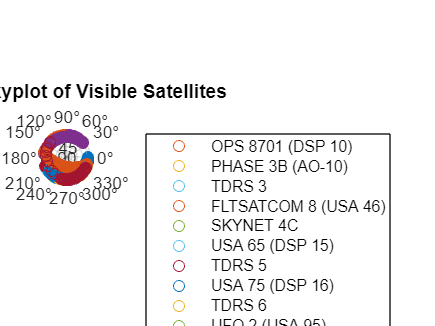

% Determine the number of satellites
numSatellites = numel(az_all);

% Generate unique colors based on the parula colormap
cmap = lines(numSatellites);

% Create a figure
figure;

% Set up custom polar-like axes
pax = polaraxes;
ax = gca;

% Set radial limits
rlim(ax, [0, 90]);

% Set number of radial ticks
numTicks = 5;

% Create custom radial ticks and labels
ticks = linspace(0, 90, numTicks);
invertedTicks = 90 - ticks;
ax.RTick = ticks;
ax.RTickLabels = arrayfun(@(x) num2str(x), invertedTicks, 'UniformOutput', false);

% Initialize a cell array to store handles for each satellite plot
plot_handles = cell(1, numSatellites);

% Initialize a cell array to store satellite names
satellite_names = cell(1, numSatellites);

% Create a waitbar to show progress
h = waitbar(0, 'Plotting Custom Skyplot...');

% Loop through each cell in az_all and el_all
for k = 1:numSatellites
    % Check if the cell is not empty
    if ~isempty(az_all{k}) && ~isempty(el_all{k})
        % Update waitbar
        waitbar(k/numSatellites, h, ['Plotting Satellite ', num2str(k), ' of ', num2str(numSatellites)]);

        % Convert azimuth and elevation to Cartesian coordinates
        [x, y] = pol2cart(deg2rad(az_all{k}), el_all{k});

        % Plot the custom skyplot using the available data for each satellite
        plot_handles{k} = polarplot(pax, deg2rad(az_all{k}), 90 - el_all{k}, 'o', 'Color', cmap(k, :));
        satellite_names{k} = satData{1, k}.SatName;
        hold on;
    end
end

% Remove empty cells
plot_handles(cellfun('isempty', plot_handles)) = [];
satellite_names(cellfun('isempty', satellite_names)) = [];

% Close the waitbar
close(h);

% Customize plot appearance
title('Todays Skyplot of Visible Satellites');
legend([plot_handles{:}], satellite_names, 'Interpreter', 'none');

% Invert the radial axis after plotting
%ax.RTick = invertedTicks;
ax.RTickLabels = arrayfun(@(x) num2str(x), invertedTicks, 'UniformOutput', false);

hold off;

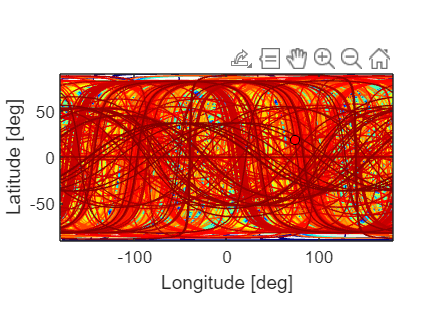

% Load a texture map
cData = imread('earthtexture.jpg');
cData = flipud(cData);

% Display the texture map
fp = figure;
fp.InvertHardcopy = 'off';
imagesc([-180, 180], [-90, 90], cData)
axis equal
axis tight
axis xy
xlabel('Longitude [deg]')
ylabel('Latitude [deg]')

% Define a color map for the satellites
cmap = jet(numSats);

% Plot the latitude and longitude of each satellite
hold on
for i = 1:numSats
    % Get the latitude and longitude of the satellite
    lat = satProp{i}.Lat;
    lon = satProp{i}.Lon;
    
    % Find orbit breaks to avoid straight jump between 180 & -180
    lngBreaks   = find((lon(1:end-1) >= 90 & lon(2:end) <= -90) | ...
                       (lon(1:end-1) <= -90 & lon(2:end) >= 90));
    latBreaks   = find((lat(1:end-1) >= 45 & lat(2:end) <= -45) | ...
                       (lat(1:end-1) <= -45 & lat(2:end) >= 45));
    orbitBreaks = unique([lngBreaks(:); latBreaks(:)]);

    % Plot segments directly, keeping track of indices
    startIdx = 1;
    for j = 1:length(orbitBreaks)
        endIdx = orbitBreaks(j);
        plot(lon(startIdx:endIdx), lat(startIdx:endIdx), ...
             'Color', cmap(i, :), 'MarkerFaceColor', cmap(i, :))
        startIdx = endIdx + 1;
    end
    % Plot the final segment if necessary
    if startIdx <= length(lon)
        plot(lon(startIdx:end), lat(startIdx:end), ...
             'Color', cmap(i, :), 'MarkerFaceColor', cmap(i, :))
    end
end

% Plot the ground station
plot(gsLon, gsLat, 'o', 'MarkerSize', 5, 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black');

hold off